clc
clear
close all
load("./sims/sim_wind10_5s.mat")

#### FORÇAS

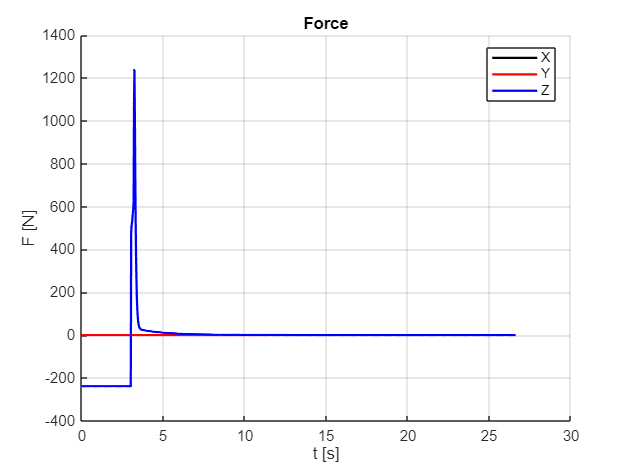

plotVariable(out.main_clock, out.F_total, "t [s]", "F [N]", "Force")

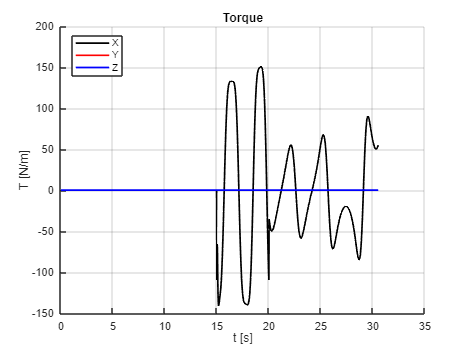

plotVariable(out.main_clock, out.T_total, "t [s]", "T [N/m]", "Torque")

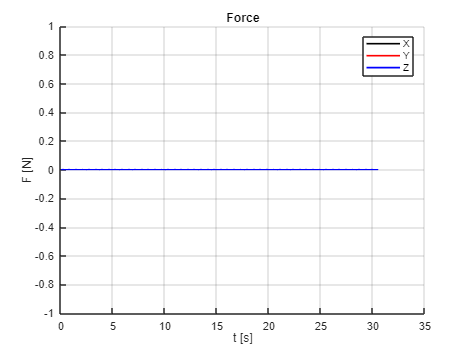

plotVariable(out.main_clock, out.F_drag_cilinder, "t [s]", "F [N]", "Force")

#### VEÍCULO

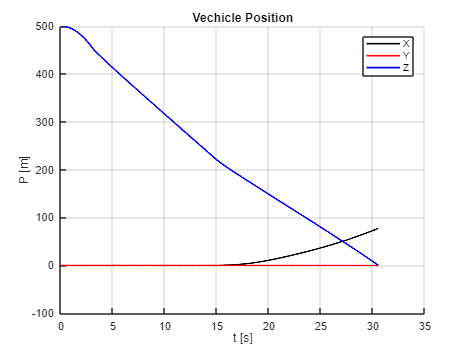

plotVariable(out.main_clock, out.vehicle_position, "t [s]", "P [m]", "Vechicle Position")

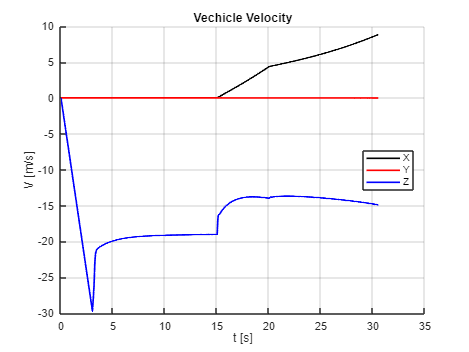

plotVariable(out.main_clock, out.vehicle_velocity, "t [s]", "V [m/s]", "Vechicle Velocity")

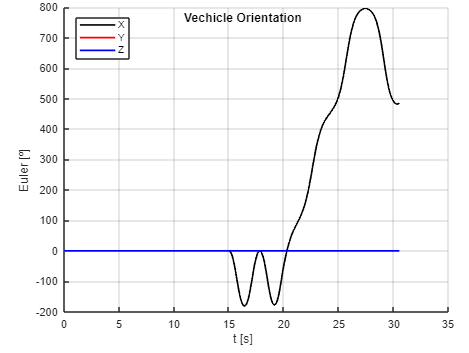

plotVariable(out.main_clock, out.vehicle_orientation, "t [s]", "Euler [º]", "Vechicle Orientation")

#### ROTOR

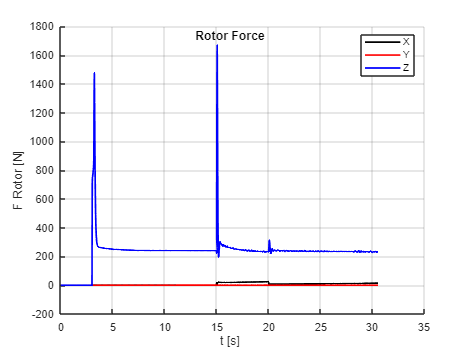

plotVariable(out.main_clock, out.F_rotor, "t [s]", "F Rotor [N]", "Rotor Force")

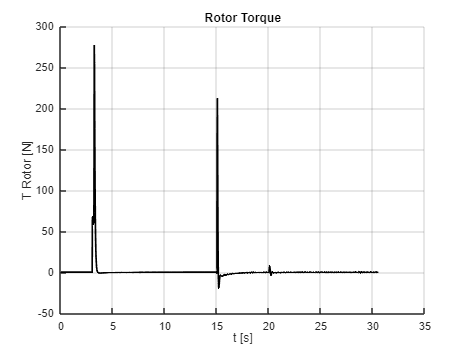

plotVariable(out.main_clock, out.T_rotor, "t [s]", "T Rotor [N]", "Rotor Torque")

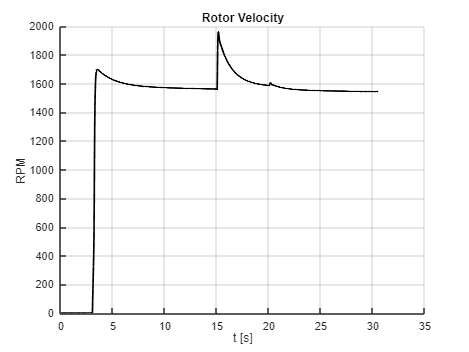

plotVariable(out.main_clock, out.rotor_rpm, "t [s]", "RPM", "Rotor Velocity")

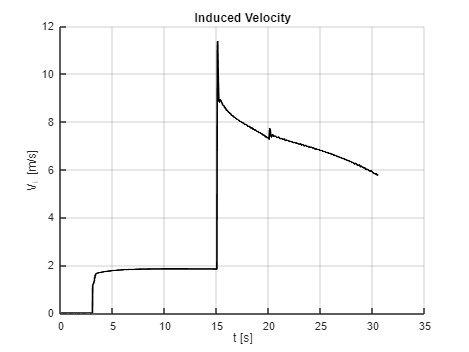

plotVariable(out.main_clock, out.rotor_induced_velocity, "t [s]", "V_i [m/s]", "Induced Velocity")

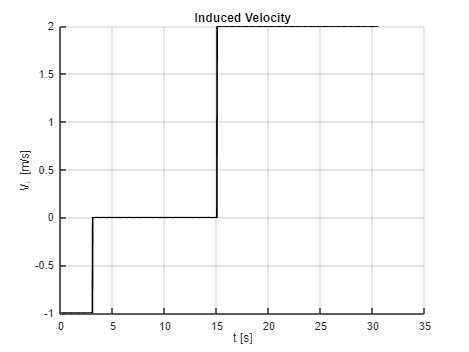

plotVariable(out.main_clock, out.rotor_operation_mode, "t [s]", "V_i [m/s]", "Induced Velocity")

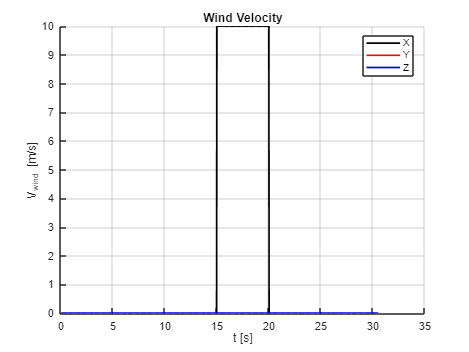

plotVariable(out.main_clock, out.wind_velocity, "t [s]", "V_{wind} [m/s]", "Wind Velocity")

### BLADE DISTRIBUTION ANALYSIS

t = 9;
azimute = 90;
[~, i] = min(abs(out.rotor_data.time - t))

i = 240

out.rotor_data.time(i)

ans = 9.0000

data_rotor = out.rotor_data.data(i)

data_rotor =   RotorAzimutalDistribution with properties:

    blade_distribution_data: [1×10 BladeDistribution]
          azimutal_position: [10×1 double]


[~, i] = min(abs(data_rotor.azimutal_position - azimute));
data_blade = data_rotor.blade_distribution_data(i);
xx = linspace(0, 1, length(data_blade.total_velocity))

xx =          0    0.0250    0.0500    0.0750    0.1000    0.1250    0.1500    0.1750    0.2000    0.2250    0.2500    0.2750    0.3000    0.3250    0.3500    0.3750    0.4000    0.4250    0.4500    0.4750    0.5000    0.5250    0.5500    0.5750    0.6000    0.6250    0.6500    0.6750    0.7000    0.7250    0.7500    0.7750    0.8000    0.8250    0.8500    0.8750    0.9000    0.9250    0.9500    0.9750    1.0000


azimutes = data_rotor.azimutal_position;

#### Velocity

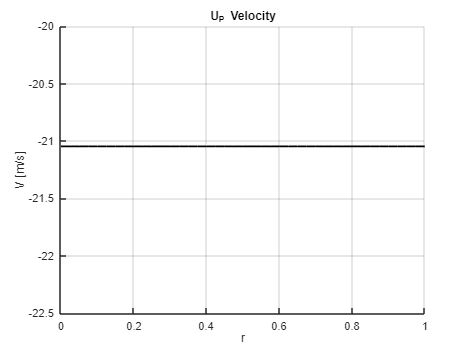

plotVariable(xx, data_blade.U_P, "r", "V [m/s]", "U_P Velocity")

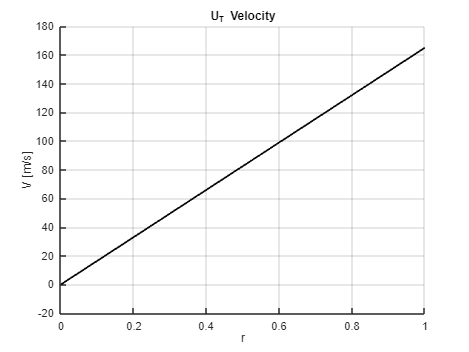

plotVariable(xx, data_blade.U_T, "r", "V [m/s]", "U_T Velocity")

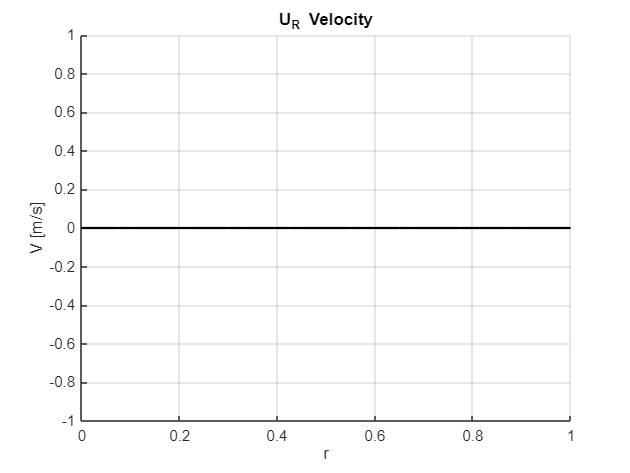

plotVariable(xx, data_blade.U_R, "r", "V [m/s]", "U_R Velocity")

#### Angles

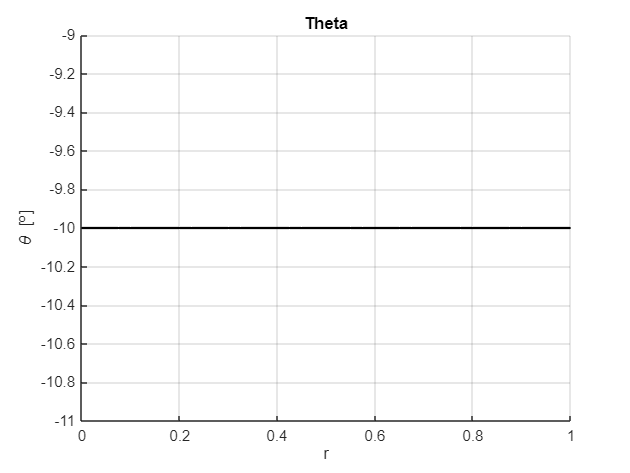

plotVariable(xx, data_blade.theta, "r", "\theta [º]", "Theta")

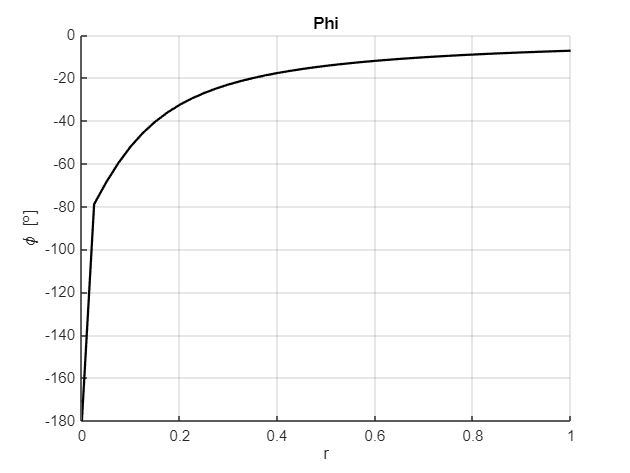

plotVariable(xx, data_blade.phi, "r", "\phi [º]", "Phi")

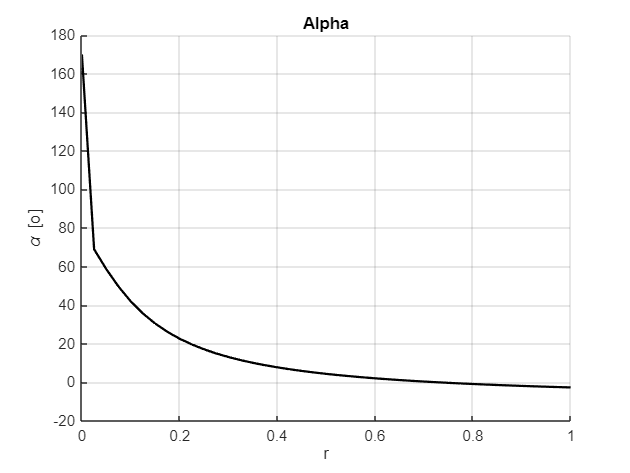

plotVariable(xx, data_blade.alpha, "r", "\alpha [o]", "Alpha")

#### Reynolds Number

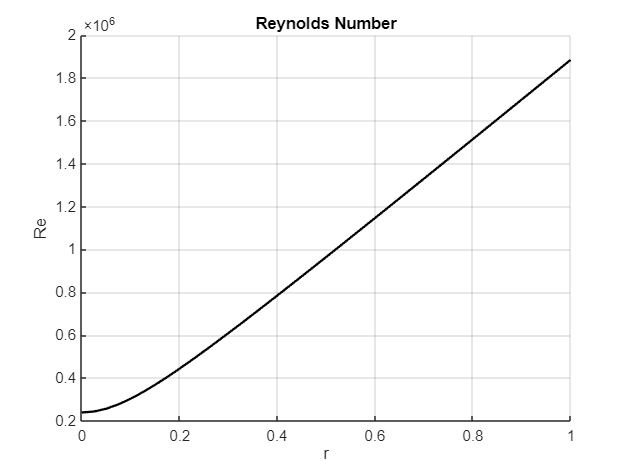

plotVariable(xx, data_blade.Re, "r", "Re", "Reynolds Number")

#### Aerodynamic Coefficients

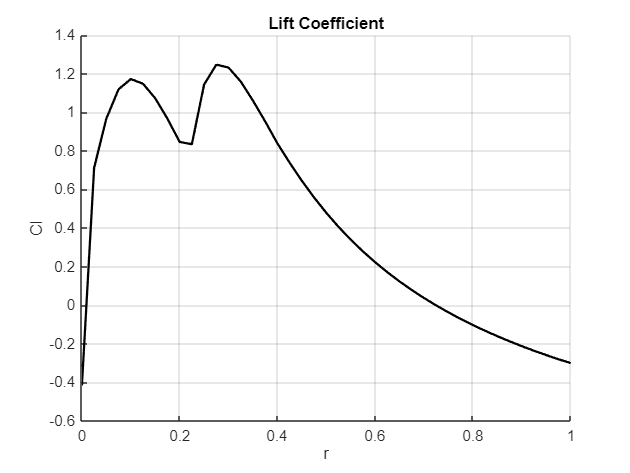

plotVariable(xx, data_blade.Cl, "r", "Cl", "Lift Coefficient")

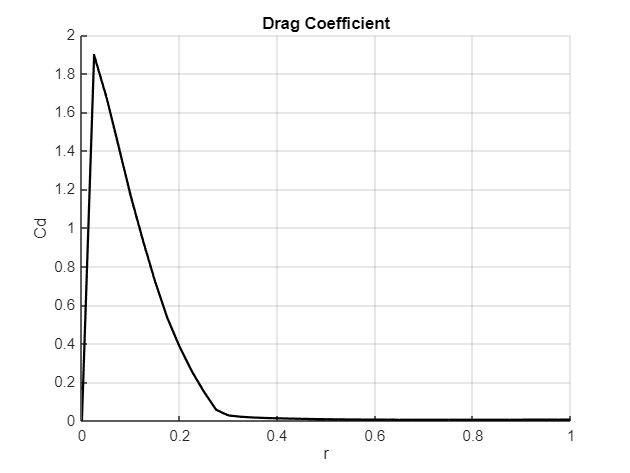

plotVariable(xx, data_blade.Cd, "r", "Cd", "Drag Coefficient")

#### Forces in Aerodynamic Frame

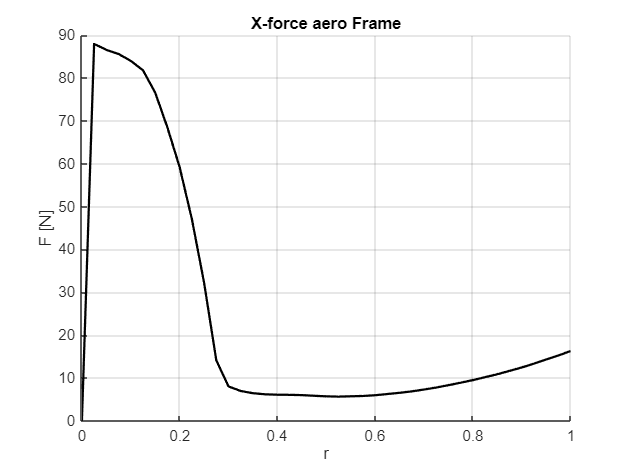

plotVariable(xx, data_blade.dF_a_x, "r", "F [N]", "X-force aero Frame")

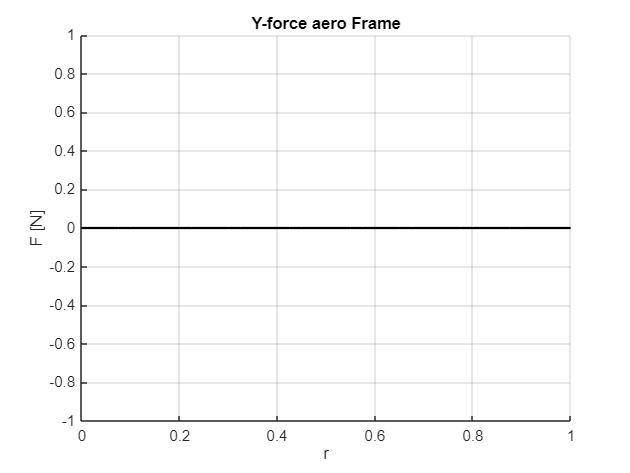

plotVariable(xx, data_blade.dF_a_y, "r", "F [N]", "Y-force aero Frame")

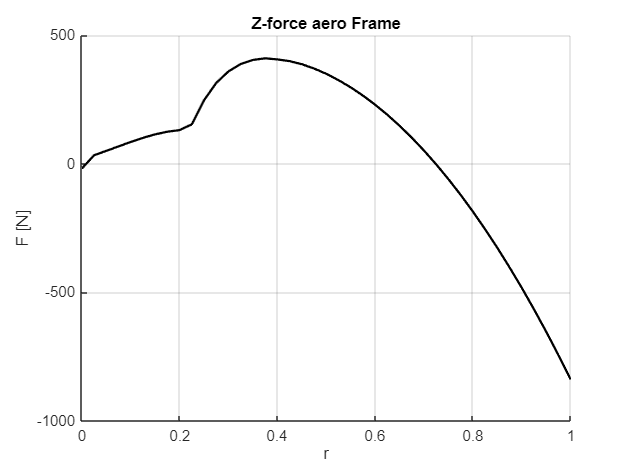

plotVariable(xx, data_blade.dF_a_z, "r", "F [N]", "Z-force aero Frame")

#### Forces in Element Frame

Aqui o sinal (-) significa que a contribuição da força aerodinâmica gera uma força que cria rotação

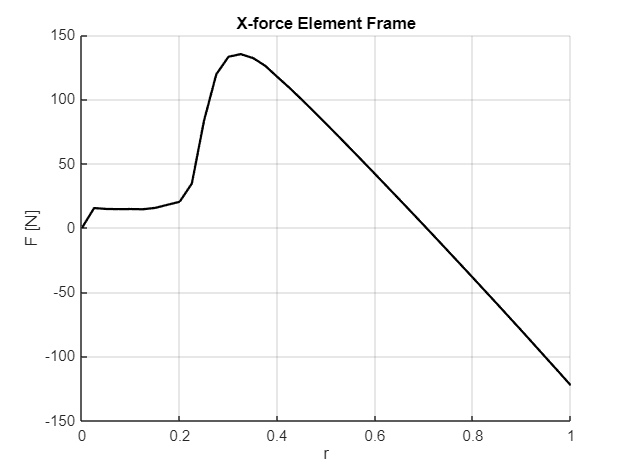

plotVariable(xx, -data_blade.dF_e_x, "r", "F [N]", "X-force Element Frame")

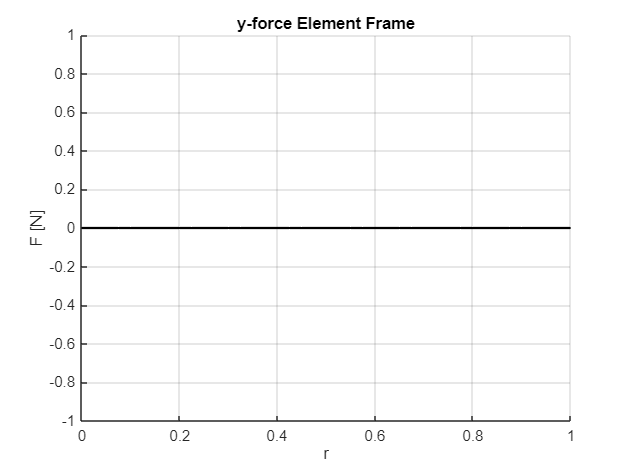

plotVariable(xx, data_blade.dF_e_y, "r", "F [N]", "y-force Element Frame")

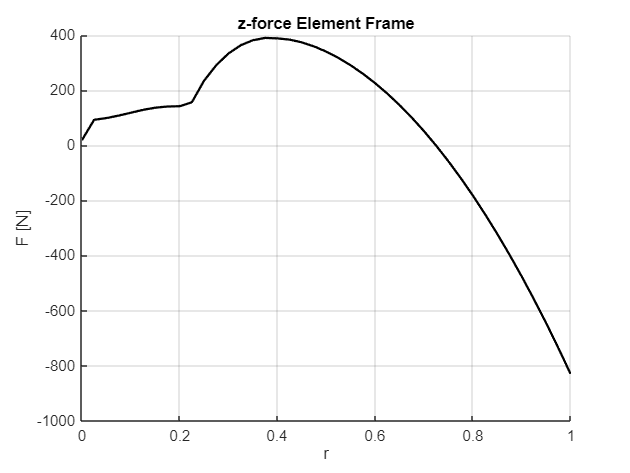

plotVariable(xx, data_blade.dF_e_z, "r", "F [N]", "z-force Element Frame")

#### Prandtl Function

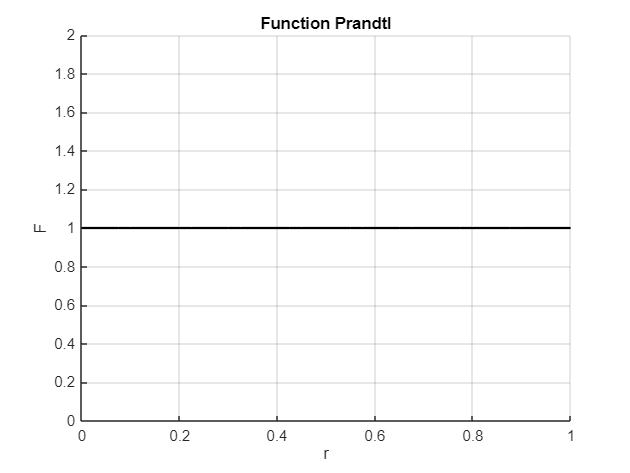

plotVariable(xx, data_blade.f_prandtl, "r", "F", "Function Prandtl")

### ROTOR DISTRIBUTION ANALYSIS

#### Forces

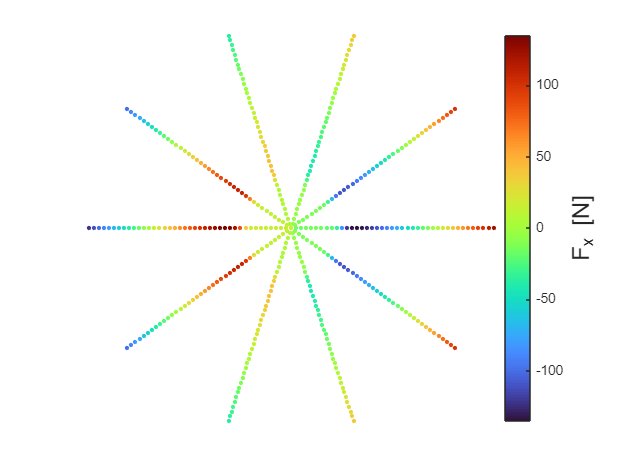

Error using saveas (line 134)
Invalid filename: 

Error in polarPlot (line 45)
    saveas(gcf, img_name, 'epsc'); % Salva como .eps em cores

for i=1:length(azimutes)
    valores(i, :) = data_rotor.blade_distribution_data(i).dF_i_x;
end
polarPlot(azimutes, xx, valores, "", "F_x [N]", "")

for i=1:length(azimutes)
    valores(i, :) = data_rotor.blade_distribution_data(i).dF_i_y;
end
polarPlot(azimutes, xx, valores, "", "F_y [N]", "")
for i=1:length(azimutes)
    valores(i, :) = data_rotor.blade_distribution_data(i).dF_i_z;
end
polarPlot(azimutes, xx, valores, "", "F_z [N]", "")